Homework #06

## 1a

i)

A=[-2, -4, 0; 4, -0, 0; 0, -8, 0; -2, -20, 0];
b=[-1; -3; -1; -3];

disp('attempt to solve with least sqs:')

attempt to solve with least sqs:


x=inv(A.'*A)*(A.'*b)

x =    NaN
   NaN
   NaN


We get NaNs.

This is because the system is formally overdetermined (the equations are contradictory), so the rank is less than N (where [M,N]=size(A)). So A^T*A, an NxN matrix, is non-invertible.

disp('(A^T * A)^-1:')

(A^T * A)^-1:


disp(inv(A.'*A))

   Inf   Inf   Inf
   Inf   Inf   Inf
   Inf   Inf   Inf



But this method requires inverting (A^T*A) so we can't use it.

ii)

disp('A^T * A:')

A^T * A:


disp(A.'*A)

    24    48     0
    48   480     0
     0     0     0



disp('A^T * b:')

A^T * b:


disp(A.'*b)

    -4
    72
     0




one_sol=pinv(A)*b

one_sol =    -0.5833
    0.2083
         0


second_sol=[one_sol(1,1); one_sol(2,1); 99]

second_sol =    -0.5833
    0.2083
   99.0000


1iii)

Assumptions: 1) Minimizes the error, but also 2) require that the solution’s norm is as small as possible. This is necessary to have 1 unique solution since A^T * A * x = A^T * b already has infinite solutions (z can vary).

x_unique=pinv(A)*b

x_unique =    -0.5833
    0.2083
         0


iv)

disp('from Matlab:')

from Matlab:


x_matlab=A\b;

disp(x_matlab)

   -0.5833
    0.2083
         0



disp('norm of x from Matlab:')

norm of x from Matlab:


disp(norm(x_matlab))

    0.6194



disp('x calculated from pseudoinverse:')

x calculated from pseudoinverse:


disp(x_unique)

   -0.5833
    0.2083
         0



disp('norm of x from pseudoinverse:')

norm of x from pseudoinverse:


disp(norm(x_unique))

    0.6194



They are the same.

## 1b

A=[3, 6, 1;
    6, 12, 2];
b=[-5;
    -4];

i) The rank of A is 1 because the second equation is the first equation x 2; A is formally underdetermined and r<M.

An x that exactly solves this cannot be found because it has two contradictory equations (same equation from A and two distinct b entries).

ii) Assumptions: 1) Minimizes the error, but also 2) require that the solution’s norm is as small as possible. This is necessary to have 1 unique solution since A^T * A * x = A^T * b already has infinite solutions:

disp('A^T * A:')

A^T * A:


disp(A.'*A)

    45    90    15
    90   180    30
    15    30     5



disp('A^T * b:')

A^T * b:


disp(A.'*b)

   -39
   -78
   -13



(all the same equation)

Calculation:

x_unique=pinv(A)*b

x_unique =    -0.1696
   -0.3391
   -0.0565


## 2

2a)

So for our least sqs solution, we want to minimize the distance between Ax and b,$|Ax-b|^2$, which is = $(Ax-b)^T(Ax-b)$

So we have an optimization problem and want to look for where the derivative = 0:


$$\frac{d}{dx}(Ax-b)^T(Ax-b)$$



$$=\frac{d}{dx}(x^TA^TAx-b^TAx-x^TA^Tb+b^Tb)$$



$$=2(A^TAx-A^Tb)=0
$$


Therefore, $A^TAx=A^Tb$ and $x=(A^TA)^{-1}(A^Tb)$

A=[-4, -1, -1;
    8, -10, 0;
    2, 5, -2;
    -7, 0, -7;
    -7, 1, -3];
b=[-7; -3; -6; -2; -9];

x=inv(A.'*A)*(A.'*b)

x =     0.0904
    0.1189
    0.8745


2b)

v1 = A(:,1);
v2 = A(:,2);
v3 = A(:,3);

y1_hat=v1 / norm(v1);

y2=v2 - ((v2.'*y1_hat).*y1_hat);

y2_hat = y2 / norm(y2);

y3=v3 - ((v3.'*y1_hat).*y1_hat) - ((v3.'*y2_hat).*y2_hat);

y3_hat = y3 / norm(y3);

Q=[y1_hat y2_hat y3_hat]

Q =    -0.2965   -0.2635    0.1672
    0.5930   -0.6870   -0.3389
    0.1482    0.5870   -0.6440
   -0.5189   -0.2840   -0.6651
   -0.5189   -0.1829   -0.0018


R=Q.'*A

R =    13.4907   -5.4111    5.1887
   -0.0000    9.8853    1.6263
    0.0000   -0.0000    5.7820


2c)

% TF said I can use Matlab to directly multiply
x_qr=(inv(R)*Q.'*b)

x_qr =     0.0904
    0.1189
    0.8745


2d)

They are the same.

## 3

3a)

Both the SVD and Covariance Matrix method give the same answer because using SVD to give U, sigma, and V, we know that U will have as columns the eigenvectors of F*F^T and be normalized ((1/N)*F*F^T). (1/N)*F*F^T is the definition of the covariance matrix, whose eigenvectors will be the PCs.

3b)

F=[-0.8, -14, 2.4, -8.4, 4, -2.4, 6, 4, 8.8;
-7.2, 22, -8.8, 15, -8, 6.4, -8, -2, -8.8;
26, 3.2, 14, -2.4, 4, -7.2, -6, -14, -18];
[M, N] = size(F);

F_centered = F;
F_means = mean(F, 2);
F_centered(1,:) = F_centered(1,:) - F_means(1,1);
F_centered(2,:) = F_centered(2,:) - F_means(2,1);
F_centered(3,:) = F_centered(3,:) - F_means(3,1);

% using SVD
[U_svd, sigma, V] = svd(F_centered);
disp('Principal Components from SVD:')

Principal Components from SVD:


for i = 1:1:length(U_svd)
    disp(U_svd(:, i))
end

    0.2300
   -0.0611
   -0.9713

   -0.4828
    0.8594
   -0.1684

    0.8450
    0.5076
    0.1682



disp('Expansion Matrix:')

Expansion Matrix:


T_svd=sigma*V.'

T_svd =   -25.0258   -7.7016  -12.5368   -0.5467   -2.5050    6.0211    7.6677   14.6111   20.0159
  -10.2662   25.0405  -11.1653   17.2642   -9.5662    7.7851   -8.8477   -1.3785   -8.8661
    0.0526   -0.1133   -0.0735    0.1237    0.0030    0.0211    0.0113    0.0217   -0.0467



% using covariance matrix
C=(1/N).*F_centered * F_centered.';
[U_cov, lambda]=eig(C);
disp('Principal Components from Covariance Matrix:')

Principal Components from Covariance Matrix:


for i = 1:1:length(U_cov)
    disp(U_cov(:, i))
end

   -0.8450
   -0.5076
   -0.1682

   -0.4828
    0.8594
   -0.1684

   -0.2300
    0.0611
    0.9713



disp('Expansion Matrix:')

Expansion Matrix:


T_cov=U_cov.' * F_centered

T_cov =    -0.0526    0.1133    0.0735   -0.1237   -0.0030   -0.0211   -0.0113   -0.0217    0.0467
  -10.2662   25.0405  -11.1653   17.2642   -9.5662    7.7851   -8.8477   -1.3785   -8.8661
   25.0258    7.7016   12.5368    0.5467    2.5050   -6.0211   -7.6677  -14.6111  -20.0159


They are the same PCs (different directions but along same eigenvectors) for both methods. Likewise, same expansion matrices, although the order of the rows depends on the order of the PCs. 

3c) Grades for different courses for different students:

From the largest eigenvalue's PC, student 1 and student 3 are somewhat oppositely correlated where student 3 is just really good at like maybe science courses, but student 1 is better at math courses.

But simultaneously from the second largest eigenvalue's PC maybe student 1 and 3 also talk to each other in class, so student 2 does the best when both student 1 and 3 aren't doing great and are distracting each other, but does worst when student 1 and 3 talking to each other helps each other out. Student 2 is oppositely correlated with both student 1 and 3.

3d)

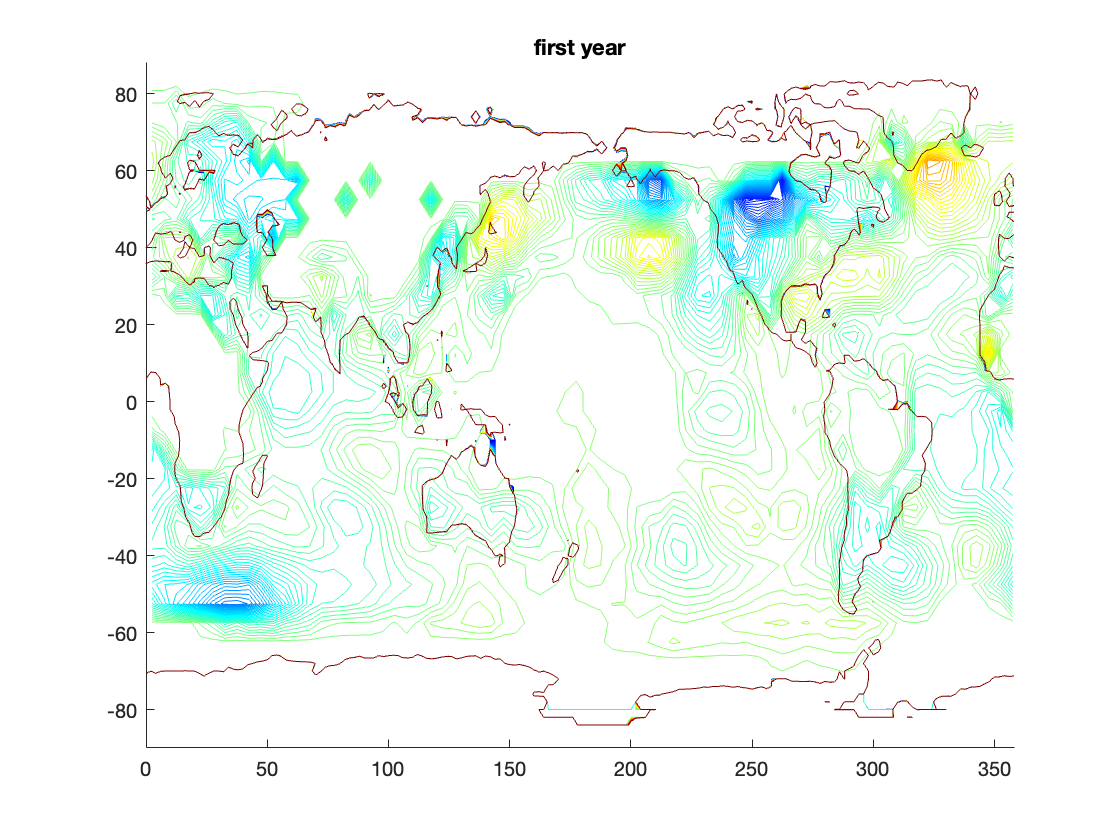

load global_temperature.mat
% lat 1x36, lon 1x72, T1 72x36x138, years 1x138
load global_topography.mat
% topo 180x90, X 180x1, Y 90x1

figure; hold on; colormap(jet)
title('first year')
TMP=permute(squeeze(T1(:,:,1)),[2,1]);
contour(lon,lat,TMP,linspace(-5,5,100))
TOP=permute(squeeze(topo(:,:,1)),[2,1]);
contour(X,Y,TOP,linspace(-5,5,100))
hold off

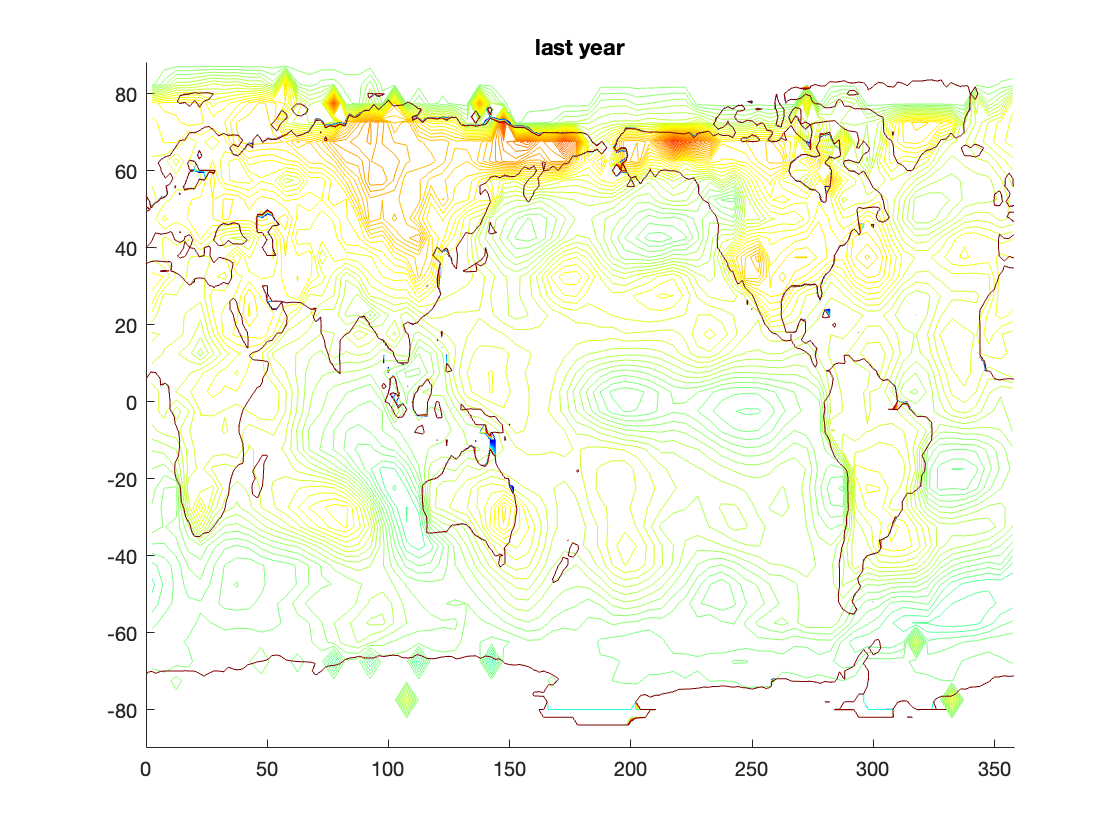


figure; hold on; colormap(jet)
title('last year')
TMP=permute(squeeze(T1(:,:,end)),[2,1]);
contour(lon,lat,TMP,linspace(-5,5,100))
TOP=permute(squeeze(topo(:,:,end)),[2,1]);
contour(X,Y,TOP,linspace(-5,5,100))
hold off

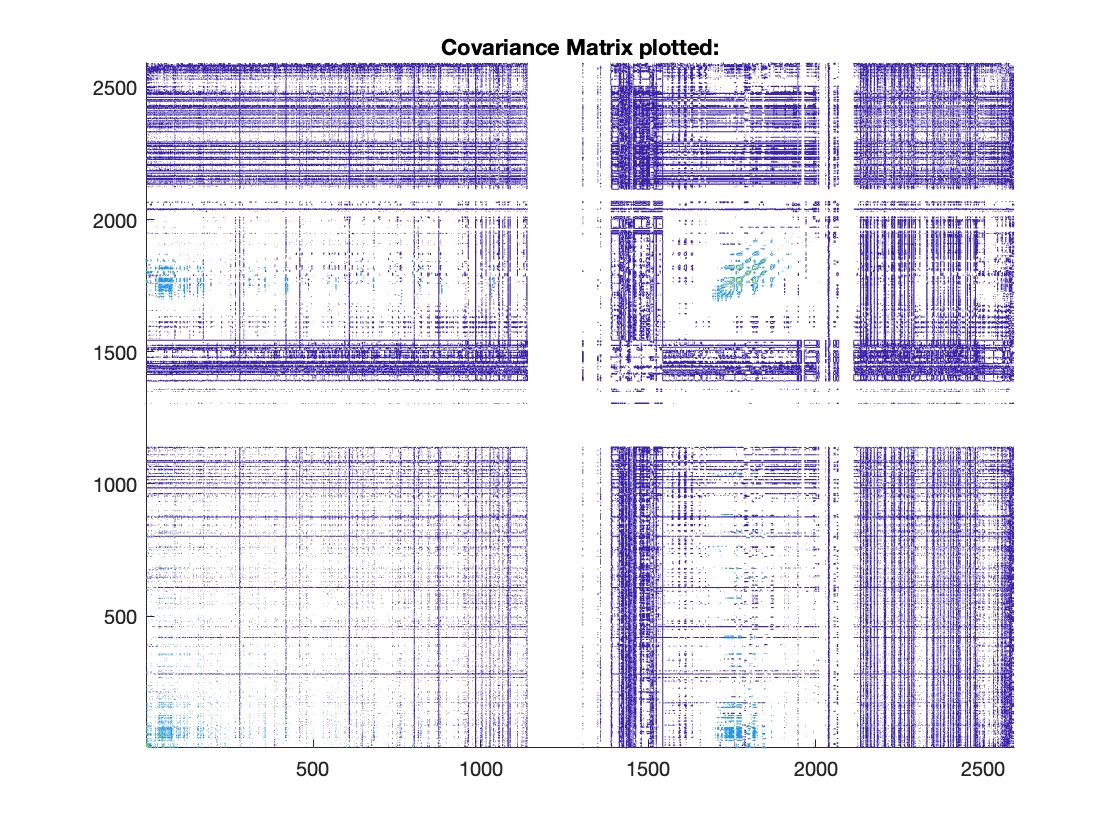


[size1, size2, size3]=size(T1);

N=size1*size2;
% reshape() will keep third dimension correctly
T1_reshape = reshape(T1, [N, size3]);
% permute rows tho so PC time series goes up
[~,idx] = sort(T1_reshape(:,1));
T1_reshape = T1_reshape(idx,:);

T2 = T1_reshape;
T_means = mean(T1_reshape, 2);

for i=1:1:N
    T2(i,:) = T2(i,:) - T_means(i,1);
end

T_cov = (1/size3).* T2 * T2.';
figure; hold on
title('Covariance Matrix plotted:')
contour(T_cov)
hold off

Top 3 PCs:

[T_U, T_lambda]=eig(T_cov);
% eig() will go from greatest lambda to smallest
pc1=T_U(:, 1);
pc2=T_U(:, 2);
pc3=T_U(:, 3);

Time series for the top 3 PCs:

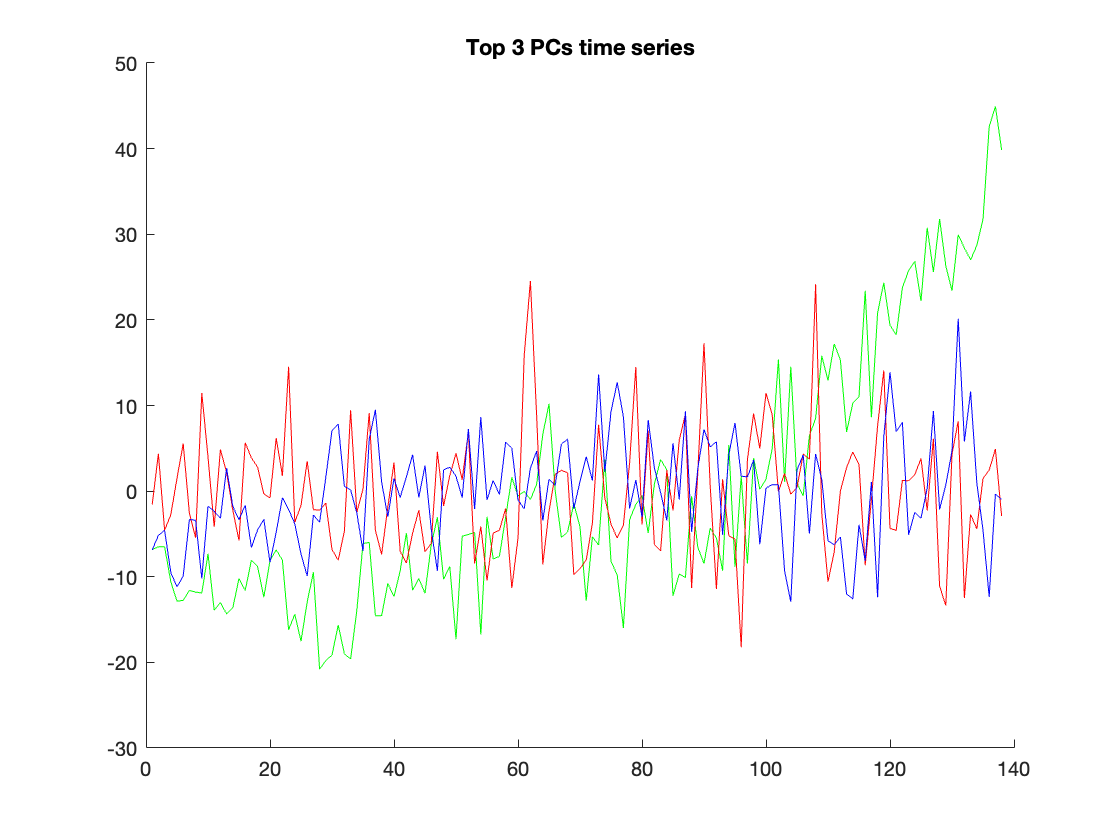

T_T = T_U.' * T2;
figure; hold on;
title('Top 3 PCs time series')
pc_color = ['g', 'r', 'b'];
for i = 1:1:3
    plot(1:size3, T_T(i, :), pc_color(1, i))
end
hold off

So the first PC that's going higher and higher is showing global temperature going higher and higher, and in fact overall, this PC explains the most variance. So that's global warming. And then the second and third PC's are likely hemisphere seasonal differences, where north and south are oppositely correlated which is why the second and third PC are oscillating in opposition to each other.

## 4

X=[ 0.1, 2.8, 3.5, 0.5, 1.2, 4, 2.1, 0, 2.9, 3.6, 0.4, 1.1;
3.8, 1.4, 0.5, 3.3, 2.7, 0, 1.7, 4.1, 1.1, 0.5, 3.5, 2.9;
9.7, -1.3, -4.2, 8.1, 5.3, -5.8, 1.8, 9.9, -1.5, -4.2, 8.2, 5.5;
9.9, -1.7, -4.3, 8.5, 5.7, -5.8, 2.3, 9.7, -1.5, -4.3, 8.3, 5.5];
Y=[-7.6, -3.6, -2.8, -6.9, -6.1, -2.2, -4.9, -7.4, -3.9, -2.7, -7, -6.1;
-2.1, -6.5, -7.4, -2.9, -3.8, -8.1, -5.1, -2.4, -6.3, -7.5, -2.8, -3.8;
-2.7, -6, -6.9, -3.1, -4, -7.3, -5, -2.7, -6, -6.9, -3.1, -4];

4a)

X_centered = X;
X_means = mean(X, 2);
for i = 1:1:length(X_means)
    X_centered(i,:) = X_centered(i,:) - X_means(i,1);
end
X_normed = X_centered ./ std(X_centered(:));

Y_centered = Y;
Y_means = mean(Y, 2);
for i = 1:1:length(Y_means)
    Y_centered(i,:) = Y_centered(i,:) - Y_means(i,1);
end
Y_normed = Y_centered ./ std(Y_centered(:));


4b)

F=[X_normed;Y_normed]

F =    -0.4207    0.2284    0.3967   -0.3246   -0.1563    0.5169    0.0601   -0.4448    0.2524    0.4207   -0.3486   -0.1803
    0.4027   -0.1743   -0.3907    0.2825    0.1382   -0.5109   -0.1022    0.4748   -0.2464   -0.3907    0.3306    0.1863
    1.7010   -0.9436   -1.6409    1.3163    0.6431   -2.0255   -0.1983    1.7491   -0.9917   -1.6409    1.3403    0.6912
    1.7330   -1.0558   -1.6809    1.3964    0.7233   -2.0416   -0.0942    1.6849   -1.0078   -1.6809    1.3484    0.6752
   -1.2963    0.7778    1.1926   -0.9333   -0.5185    1.5037    0.1037   -1.1926    0.6222    1.2444   -0.9852   -0.5185
    1.4475   -0.8340   -1.3006    1.0327    0.5660   -1.6636   -0.1080    1.2920   -0.7302   -1.3525    1.0846    0.5660
    1.0932   -0.6179   -1.0846    0.8858    0.4191   -1.2920   -0.0994    1.0932   -0.6179   -1.0846    0.8858    0.4191


[U, sigma, V_T]=svd(F)

U =     0.1297   -0.2030   -0.1036    0.0488   -0.0956    0.9328   -0.2229
   -0.1251    0.5329    0.3742   -0.1554   -0.1040   -0.0008   -0.7248
   -0.5154    0.5446    0.0344   -0.1519   -0.0716    0.3260    0.5496
   -0.5245   -0.2051   -0.6543   -0.3434   -0.1862   -0.1166   -0.2976
    0.3780    0.3970   -0.4529   -0.2838    0.6398    0.0549   -0.0383
   -0.4158   -0.3964    0.4057   -0.2420    0.6610    0.0843   -0.0533
   -0.3333    0.1463   -0.2241    0.8327    0.3065   -0.0003   -0.1731


sigma =     9.0511         0         0         0         0         0         0         0         0         0         0         0
         0    0.2204         0         0         0         0         0         0         0         0         0         0
         0         0    0.1521         0         0         0         0         0         0         0         0         0
         0         0         0    0.0584         0         0         0         0         0         0         0         0
         0         0         0         0    0.0380         0         0         0         0         0         0         0
         0         0         0         0         0    0.0209         0         0         0         0         0         0
         0         0         0         0         0         0    0.0151         0         0         0         0         0


V_T =    -0.3698   -0.2604    0.3177   -0.1512    0.4297    0.4848    0.2735    0.2378    0.3271   -0.0989   -0.0425   -0.0463
    0.2141    0.5092    0.1138    0.1845    0.4602    0.0622   -0.4823    0.1934    0.1788   -0.0102   -0.2862    0.2194
    0.3514   -0.0336    0.2055   -0.3449    0.1087   -0.5918    0.3104    0.1140    0.3800    0.1067   -0.2376   -0.1745
   -0.2835   -0.0149   -0.5641    0.2267    0.1138   -0.0571    0.1799   -0.3672    0.4288    0.2419   -0.3096    0.1678
   -0.1458   -0.2792   -0.0828   -0.2744   -0.2449   -0.0699   -0.6667    0.0105    0.5052   -0.1455    0.1564   -0.0914
    0.4349    0.0254   -0.2967    0.2315   -0.1209    0.1477    0.2842    0.2582    0.3491   -0.4699    0.3212    0.1973
    0.0320   -0.3899   -0.3826   -0.0814    0.0292   -0.0437   -0.0880    0.6731   -0.2501    0.2571   -0.2283    0.2229
   -0.3596    0.5663    0.0056   -0.0650   -0.5225    0.0721    0.1507    0.4112    0.1663    0.1244   -0.1110   -0.1423
    0.2042   -0.3176    0.

for i = 1:1:5
    sigma_subset=sigma(1:i, 1:i);
    disp(['using ' num2str(i) ' PCs:'])
    percent_explained_var=100*sum(sigma_subset(:))/sum(sigma(:))
end

using 1 PCs:


percent_explained_var = 94.7162

using 2 PCs:


percent_explained_var = 97.0225

using 3 PCs:


percent_explained_var = 98.6146

using 4 PCs:


percent_explained_var = 99.2261

using 5 PCs:


percent_explained_var = 99.6235

So just the first PC is enough to explain more than 50% of the total variance.

disp('First PC:')

First PC:


disp(U(:, 1))

    0.1297
   -0.1251
   -0.5154
   -0.5245
    0.3780
   -0.4158
   -0.3333



So from this one PC, it looks like the first row of X (4 total rows) is correlated with the first row of Y (the bottom 3 rows) and then the rest of the rows of X and Y are correlated together in the opposite direction.

4c)

X_normed

X_normed =    -0.4207    0.2284    0.3967   -0.3246   -0.1563    0.5169    0.0601   -0.4448    0.2524    0.4207   -0.3486   -0.1803
    0.4027   -0.1743   -0.3907    0.2825    0.1382   -0.5109   -0.1022    0.4748   -0.2464   -0.3907    0.3306    0.1863
    1.7010   -0.9436   -1.6409    1.3163    0.6431   -2.0255   -0.1983    1.7491   -0.9917   -1.6409    1.3403    0.6912
    1.7330   -1.0558   -1.6809    1.3964    0.7233   -2.0416   -0.0942    1.6849   -1.0078   -1.6809    1.3484    0.6752


Y_normed.'

ans =    -1.2963    1.4475    1.0932
    0.7778   -0.8340   -0.6179
    1.1926   -1.3006   -1.0846
   -0.9333    1.0327    0.8858
   -0.5185    0.5660    0.4191
    1.5037   -1.6636   -1.2920
    0.1037   -0.1080   -0.0994
   -1.1926    1.2920    1.0932
    0.6222   -0.7302   -0.6179
    1.2444   -1.3525   -1.0846


[pic 4c]

[M,N]=size(X_normed);
C=X_normed*Y_normed.'*(1/N)

C =     0.3343   -0.3678   -0.2951
   -0.3221    0.3544    0.2847
   -1.3290    1.4622    1.1730
   -1.3531    1.4887    1.1935


The covariance matrix is the variability between the two datasets, X and Y. So, C(1,1) would be the covariance of the 1st component for X and the 1st Y component.

4d)

[U, sigma, V_T]=svd(C)

U =    -0.1712    0.1486    0.6814    0.6959
    0.1650   -0.6093   -0.4619    0.6230
    0.6807   -0.4570    0.5186   -0.2427
    0.6929    0.6308   -0.2310    0.2620


sigma =     3.3758         0         0
         0    0.0006         0
         0         0    0.0000
         0         0         0


V_T =    -0.5784   -0.3424   -0.7404
    0.6364    0.3784   -0.6722
    0.5104   -0.8600   -0.0010



for i = 1:1:3
    sigma_subset=sigma(1:i, 1:i);
    disp(['using ' num2str(i) ' PCs:'])
    percent_explained_var=100*sum(sigma_subset(:))/sum(sigma(:))
end

using 1 PCs:


percent_explained_var = 99.9826

using 2 PCs:


percent_explained_var = 99.9998

using 3 PCs:


percent_explained_var = 100

Just the first singular value is able to explain 99% of the variance.

The U vectors represent the components in the X dataset. The V vectors represent the components in the Y dataset.

4e)

C_squared = C.^2;
total_covariance = sum(C_squared(:))

total_covariance = 11.3962


sigma_squared = sigma.^2;

sigma_squared =    11.3962         0         0
         0    0.0000         0
         0         0    0.0000
         0         0         0


sum_singular_values = sum(sigma_squared(:))

sum_singular_values = 11.3962

They are in fact equal.

Because the total covariance is the sum of the squared singular values, then the covariance contribution by one mode is the fraction of that one's squared singular value over the total sum of squared singular values used.

sigma_squared

using 1 PCs:


percent_explained_var = 100.0000

using 2 PCs:


percent_explained_var = 100.0000

using 3 PCs:


percent_explained_var = 100

So since sigma_squared is all basically zeros except the first singular value, we only need 1 mode to explain more than 50% of the covariance.

Total variance is the spread of the dataset while total covariance is the correlational directional between two varying data.